**6.2.2 Poles and zeros of z-transform **

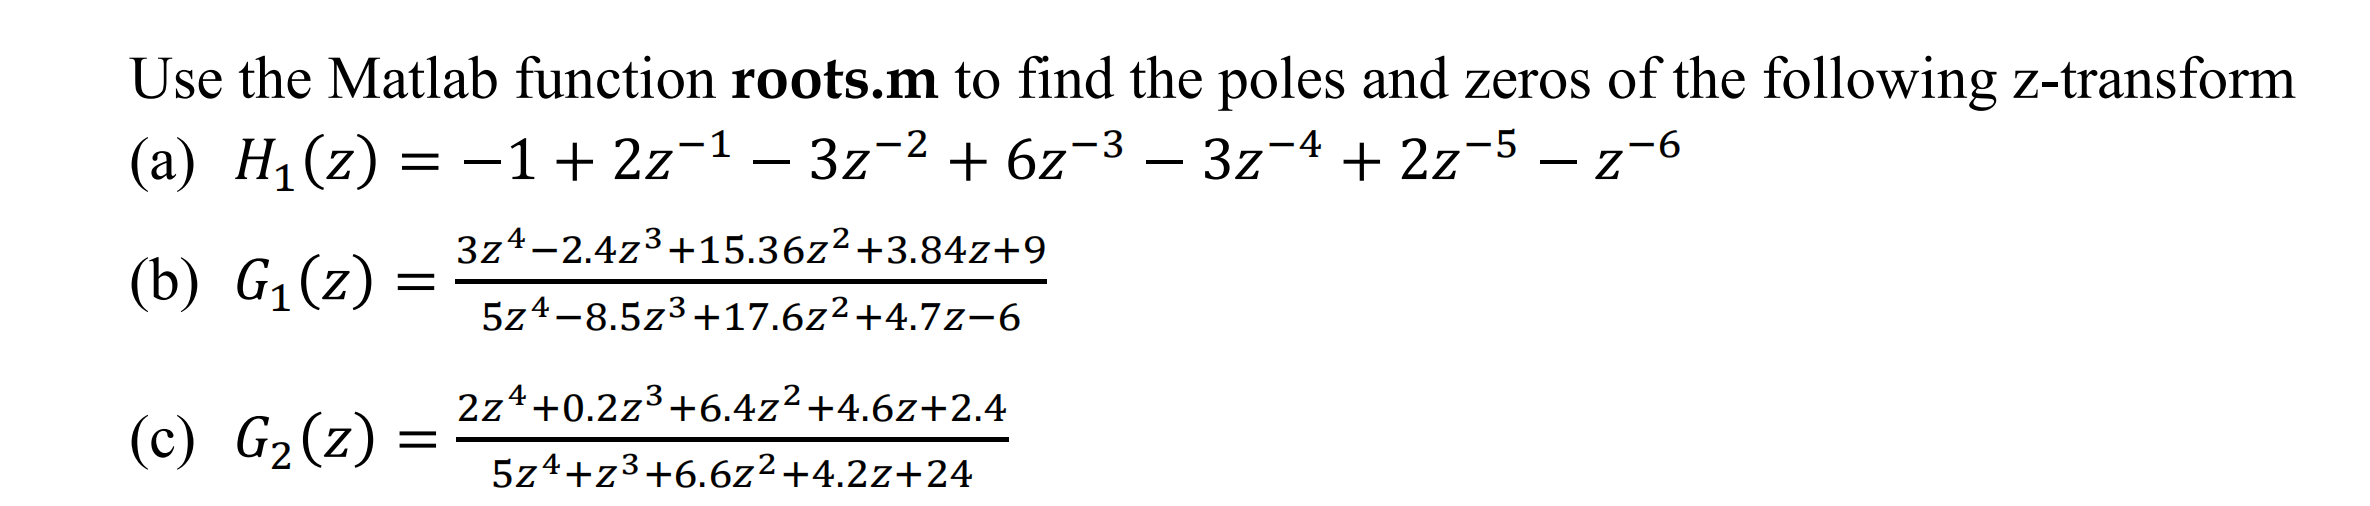


clear;
close all;
clc;
P1 = [-1 2 -3 6 -3 2 -1];
D1 = [1 zeros(1,6)];
P2 = [3 -2.4 15.36 3.84 9];
D2 = [5 -8.5 17.6 4.7 -6];
P3 = [2 0.2 6.4 4.6 2.4];
D3 = [5 1 6.6 4.2 24];

zeros1 = roots(P1)

zeros1 =    1.8054 + 0.0000i
  -0.1269 + 1.5457i
  -0.1269 - 1.5457i
  -0.0528 + 0.6426i
  -0.0528 - 0.6426i
   0.5539 + 0.0000i


poles1 = roots(D1)

poles1 =      0
     0
     0
     0
     0
     0


zeros2 = roots(P2)

zeros2 =    0.6000 + 2.1541i
   0.6000 - 2.1541i
  -0.2000 + 0.7483i
  -0.2000 - 0.7483i


poles2 = roots(D2)

poles2 =    0.9000 + 1.7861i
   0.9000 - 1.7861i
  -0.6000 + 0.0000i
   0.5000 + 0.0000i


zeros3 = roots(P3)

zeros3 =    0.3296 + 1.7980i
   0.3296 - 1.7980i
  -0.3796 + 0.4637i
  -0.3796 - 0.4637i


poles3 = roots(D3)

poles3 =    0.8272 + 1.2744i
   0.8272 - 1.2744i
  -0.9272 + 1.1045i
  -0.9272 - 1.1045i




display(max(abs(poles1)));

     0



display(min(abs(poles1)));

     0



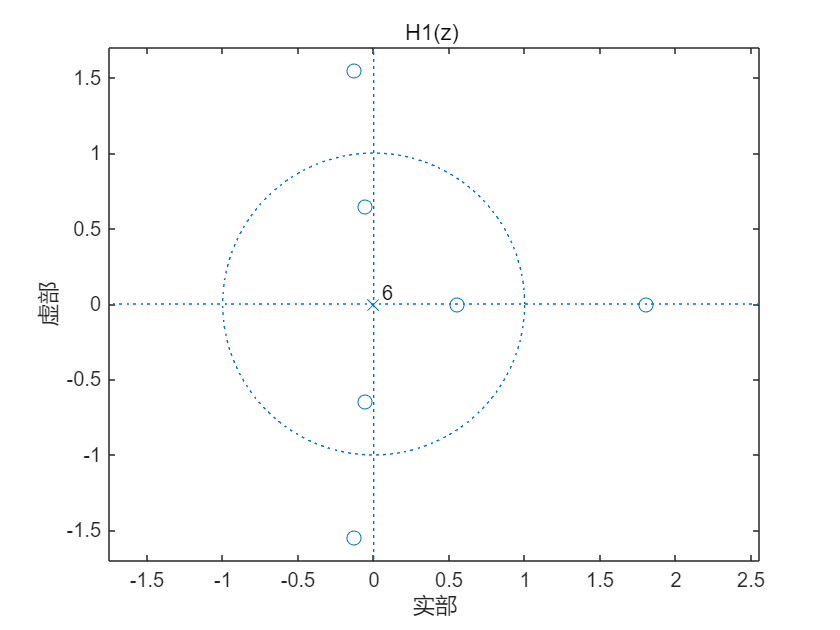

figure
zplane(zeros1,poles1);
title('H1(z) ');

%left-sided ROC: impossible，pole全0
%right-sided ROC:|𝑧| > 0
%two-sided ROC:impossible


display(max(abs(poles2)));

    2.0000



display(min(abs(poles2)));

    0.5000



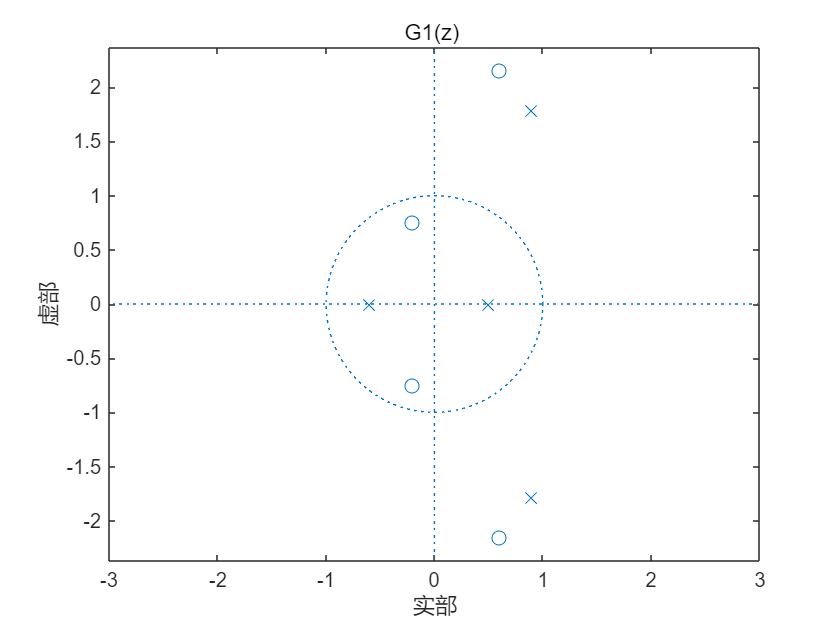

figure
zplane(zeros2,poles2);
title('G1(z) ');

%left-sided ROC:|z|<0.5
%right-sided ROC:|z|>2
%two-sided ROC:0.6<|z|<2


display(max(abs(poles3)));

    1.5193



display(min(abs(poles3)));

    1.4421



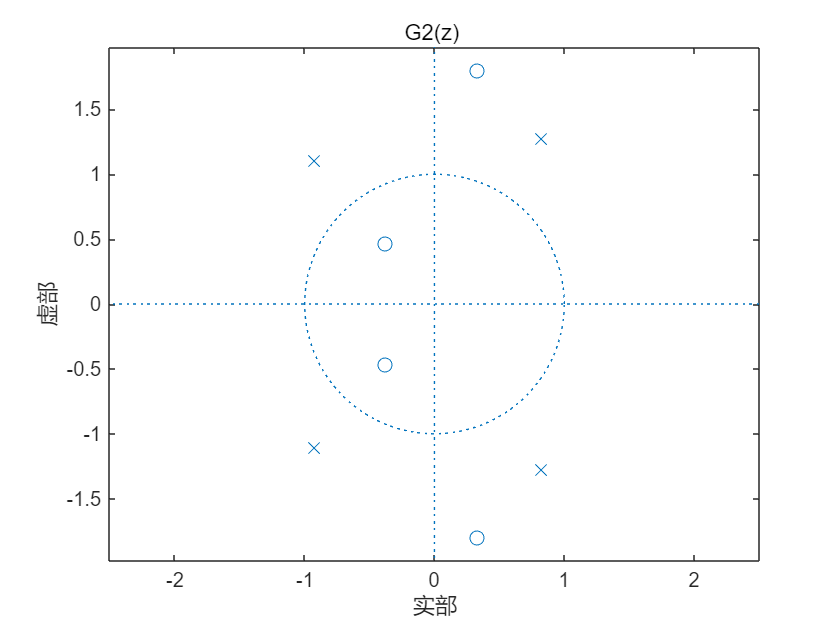

figure
zplane(zeros3,poles3);
title('G2(z) ');


%left-sided ROC:|z|<1.4421
%right-sided ROC:|z|>1.5193
%two-sided ROC:1.4421<|z|<1.5193

For right-sided sequences: ROC extends outward from the outermost pole to infinity. 

For left-sided: ROC inwards from the innermost pole to the original point. 

For two-sided: ROC either is a ring or do not exist. 

**6.2.3 z-transform and frequency response**

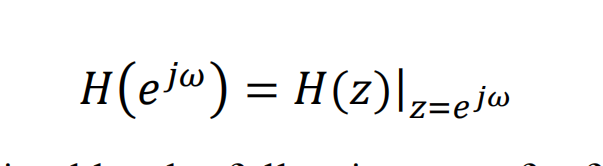

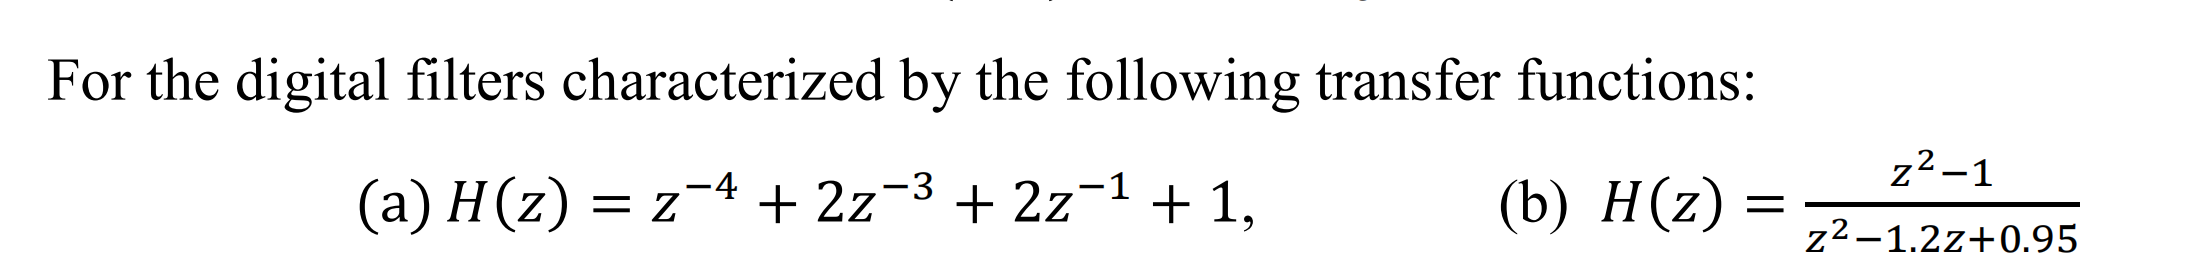

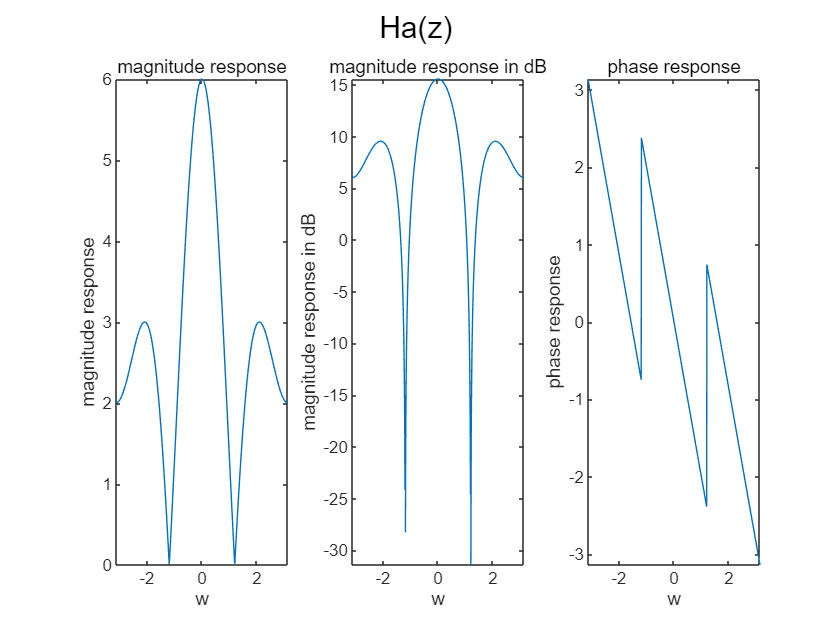

P1 = [1 2 0 2 1];
D1 = [1 0 0 0 0];

P2 = [1 0 -1];
D2 = [1 -1.2 0.95];

[mag1,phase1]=FreRes(P1,D1);
[mag2,phase2]=FreRes(P2,D2);

syms w;
figure()
sgtitle('Ha(z) ');
subplot(1,3,1);
fplot(w,mag1,[-pi,pi]);
xlabel('w');
ylabel('magnitude response');
title('magnitude response');

subplot(1,3,2);
fplot(w,20*log10(mag1),[-pi,pi]);
xlabel('w');
ylabel('magnitude response in dB');
title('magnitude response in dB');

subplot(1,3,3);
fplot(w,phase1,[-pi,pi]);
xlabel('w');
ylabel('phase response');
title('phase response');

figure()
sgtitle('Hb(z) ');
subplot(1,3,1);
fplot(w,mag2,[-pi,pi]);66666

ans = 66666

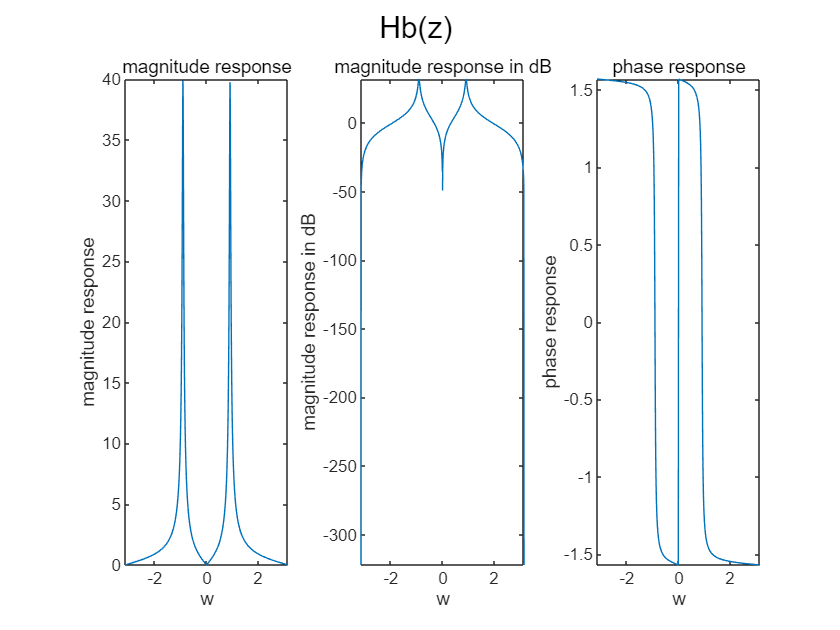

xlabel('w');
ylabel('magnitude response');
title('magnitude response');

subplot(1,3,2);
fplot(w,20*log10(mag2),[-pi,pi]);
xlabel('w');
ylabel('magnitude response in dB');
title('magnitude response in dB');

subplot(1,3,3);
fplot(w,phase2,[-pi,pi]);
xlabel('w');
ylabel('phase response');
title('phase response');

**6.2.4 Inverse z-transform **

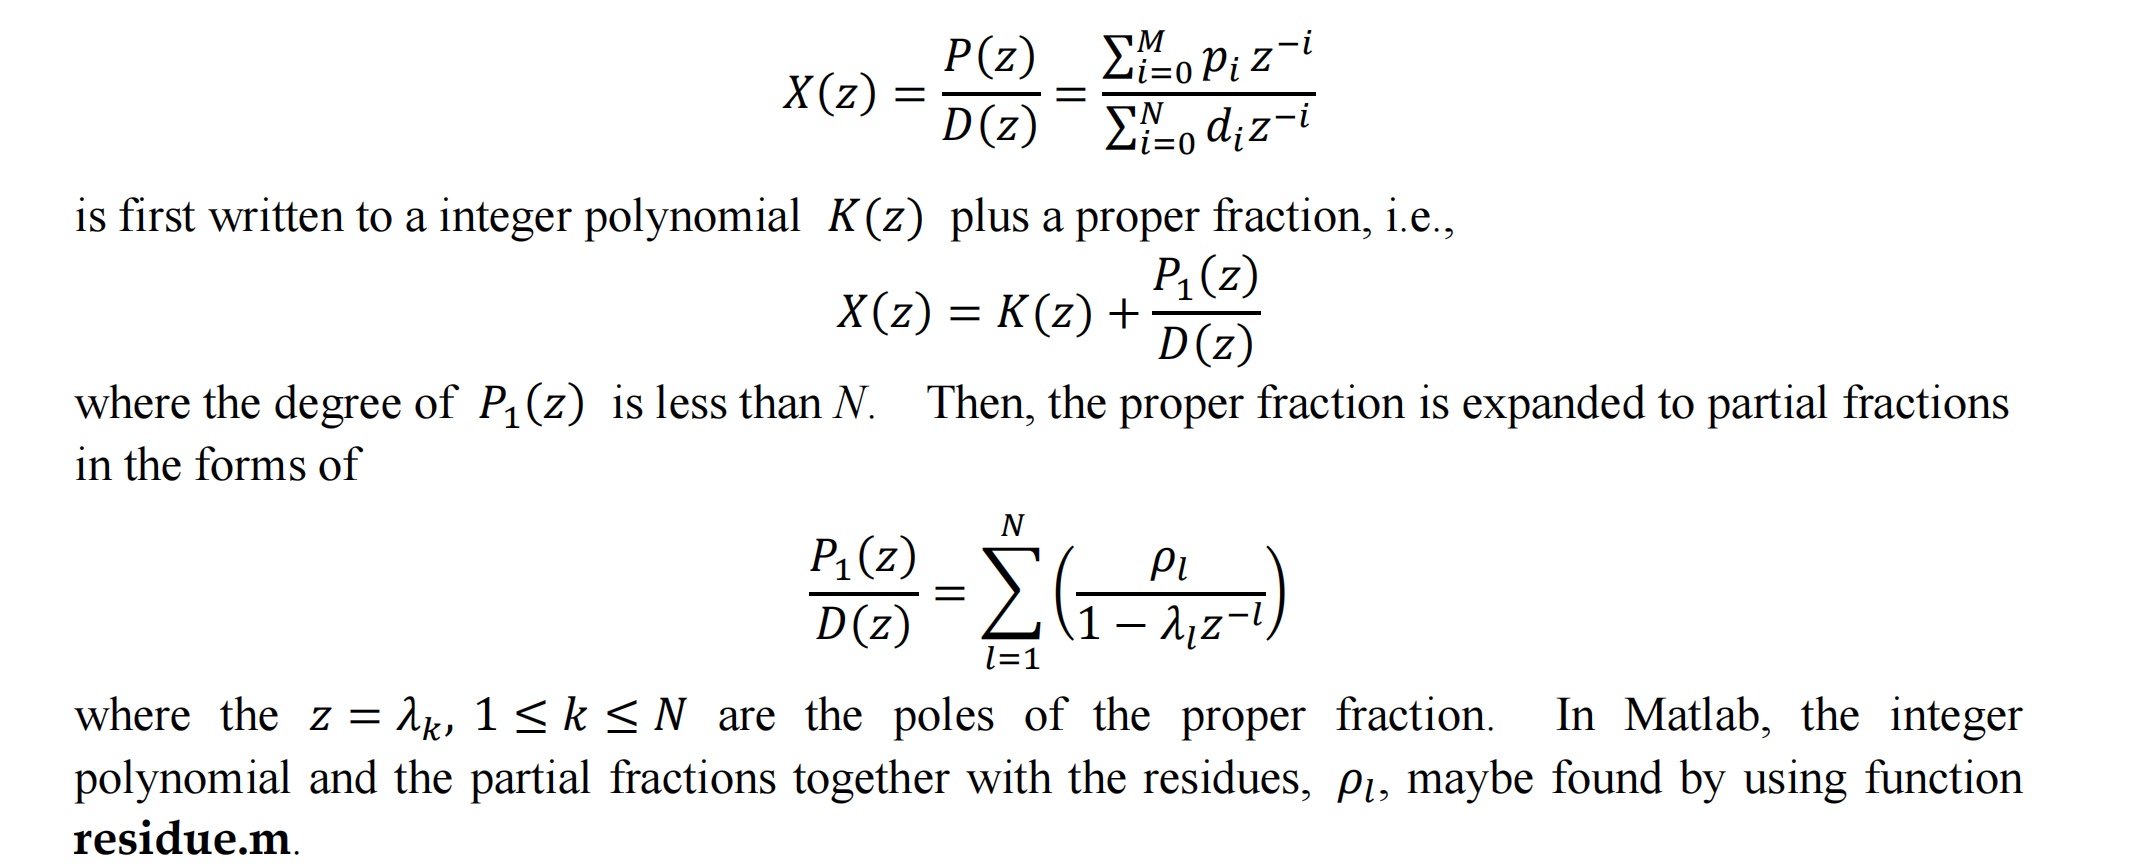

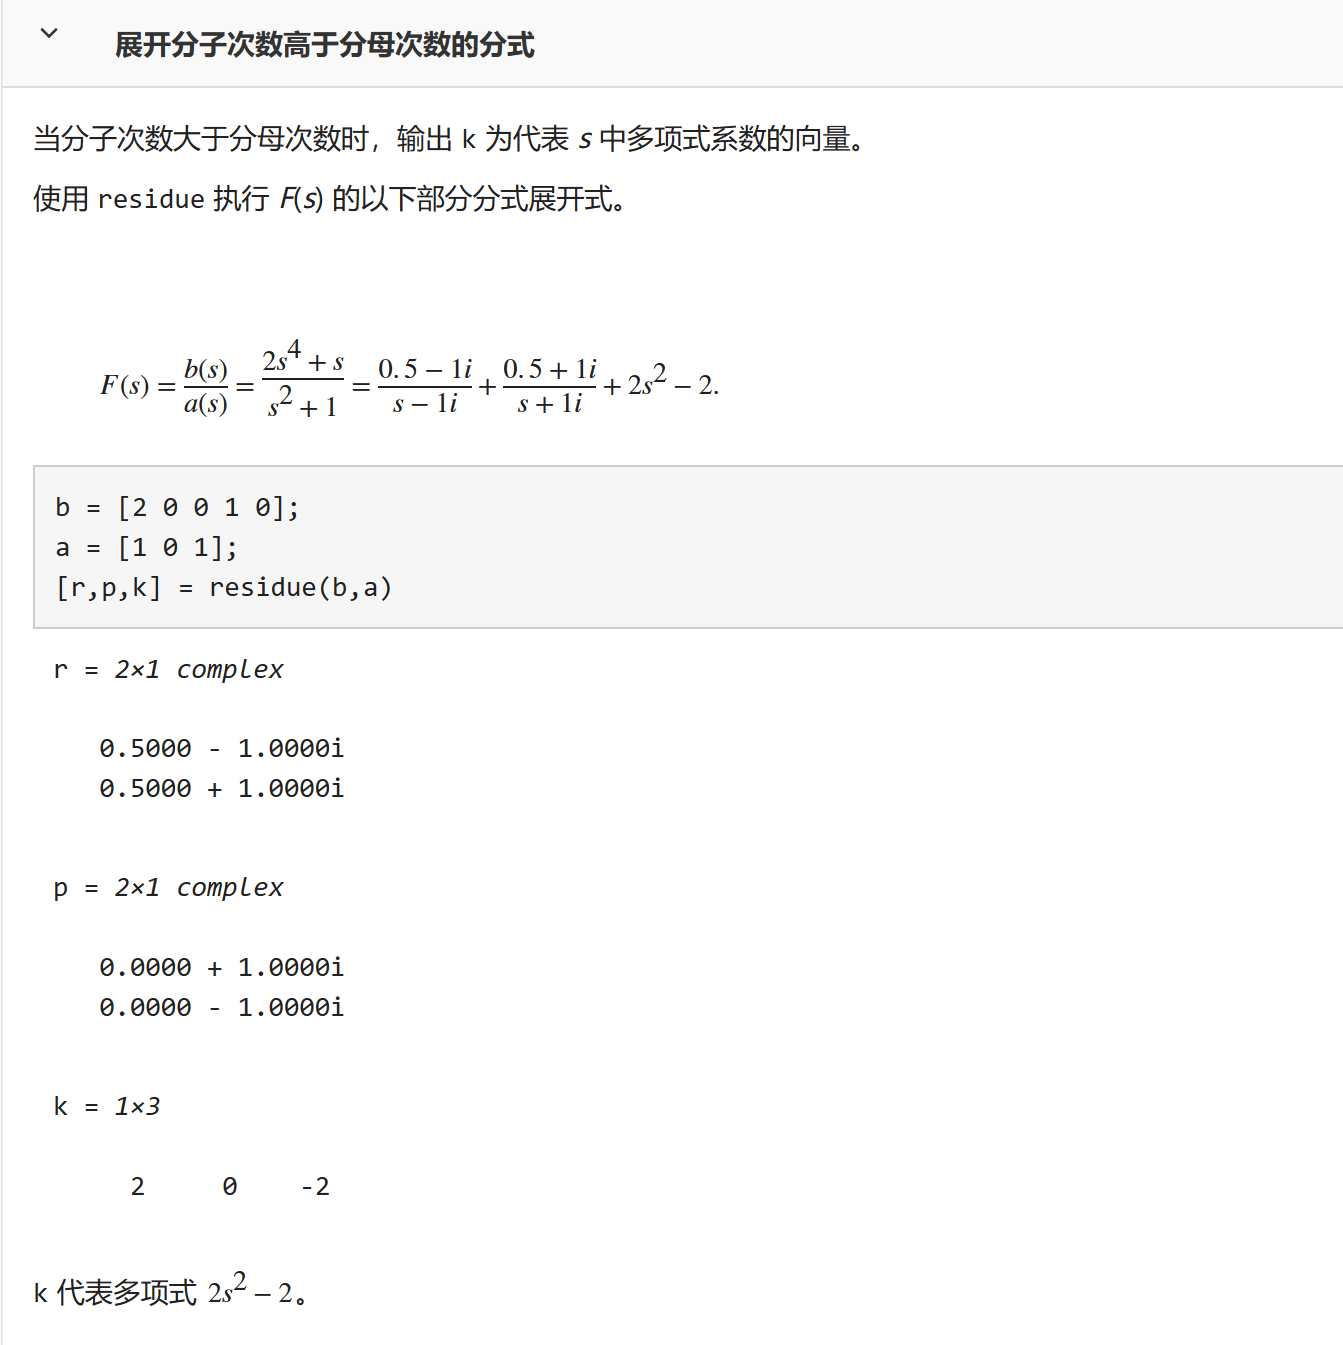

find the partial fraction expansion of the following two z-transforms: 令s=z^-1

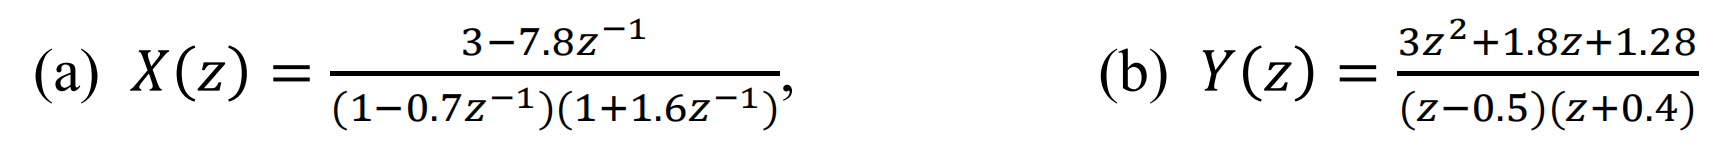

P1 = [-7.8 3];
D1 = [-1.12 0.9 1];
P2 = [1.28 1.8 3];
D2 = [-0.2 -0.1 1];
[r, p, k] = residue(P1,D1);
[rou1,p1,k1] = residue_expansion(P1,D1);
[rou2,p2,k2] = residue_expansion(P2,D2);

display(rou1);

rou1 =    -2.4783
    5.4783


display(p1);

p1 =     0.7000
   -1.6000


display(k1);


k1 =

     []




display(rou2);

rou2 =     2.8889
    6.5111


display(p2);

p2 =    -0.4000
    0.5000


display(k2);

k2 = -6.4000

**6.2.5 Stability Conditions **

A stable causal LTI system has all poles inside unit circle. 

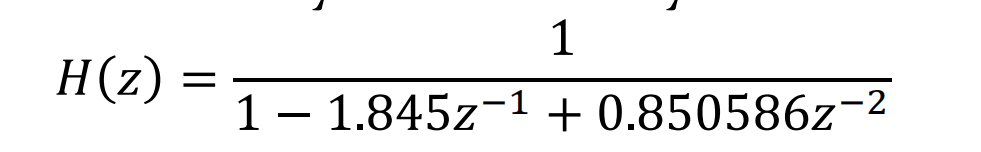

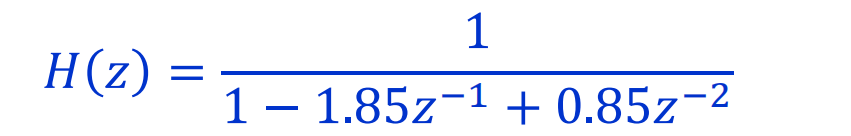

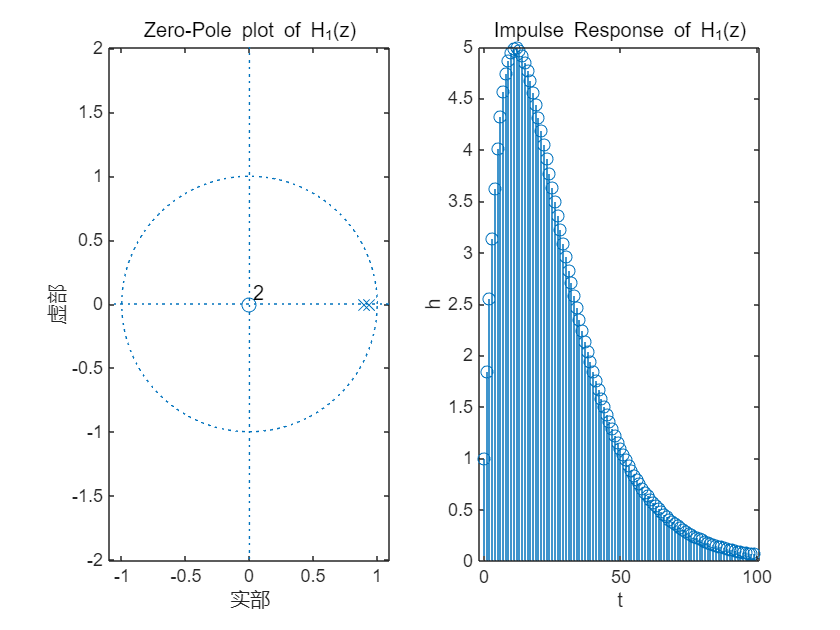

poles1 = [0.943 0.902]; zeros1 = [0 0];
b1 = [1]; a1 = [1 -1.845 0.850586];
[h1,t1] = impz(b1,a1,100);
poles2 = [1 0.85]; zeros2 = [0 0];
b2 = [1]; a2 = [1 -1.85 0.85];
[h2,t2] = impz(b2,a2,100);

figure(); 
subplot(1,2,1);
zplane(zeros1',poles1');
title('Zero-Pole plot of H_1(z)');

subplot(1,2,2);
stem(t1,h1);
xlabel('t');
ylabel('h');
title('Impulse Response of H_1(z)');

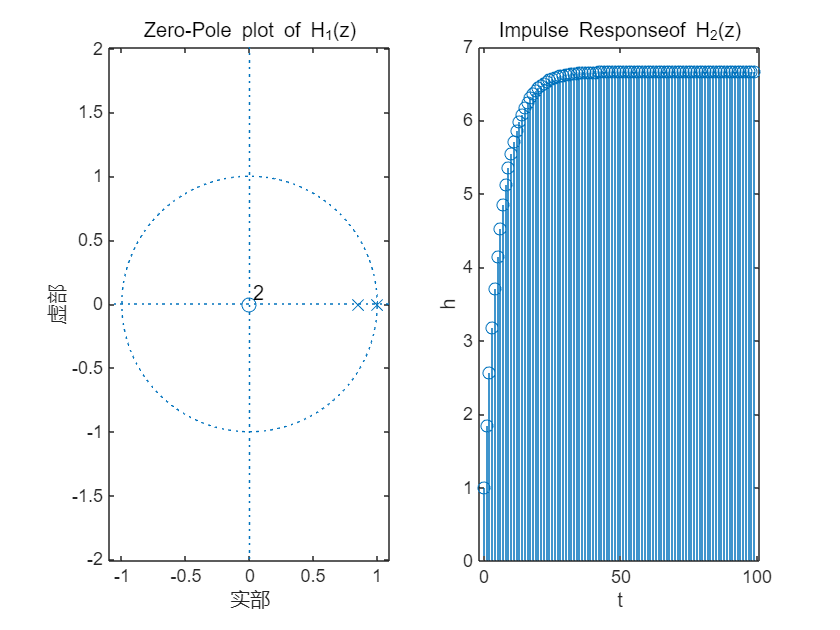


figure();
subplot(1,2,1);
zplane(zeros2',poles2');
title('Zero-Pole plot of H_1(z)');

subplot(1,2,2);
stem(t2,h2);
xlabel('t');
ylabel('h');
title('Impulse Responseof H_2(z)');


%Poles of H1(z) are all in unit circle, it's stable
%One pole of H2(z) is  on unit circle, it's unstable

即使原始设计中所有极点都位于单位圆内（确保了滤波器的稳定性），量化后极点的这种微小移动可能会导致它们穿过单位圆，落入单位圆外部。当极点位于单位圆外时，滤波器的某些部分的响应会随着时间的推移而指数增长，导致系统不稳定。

**6.3 Linear Phase FIR Filters**

**6.3.1 Four Types of Linear Phase FIR Filters **

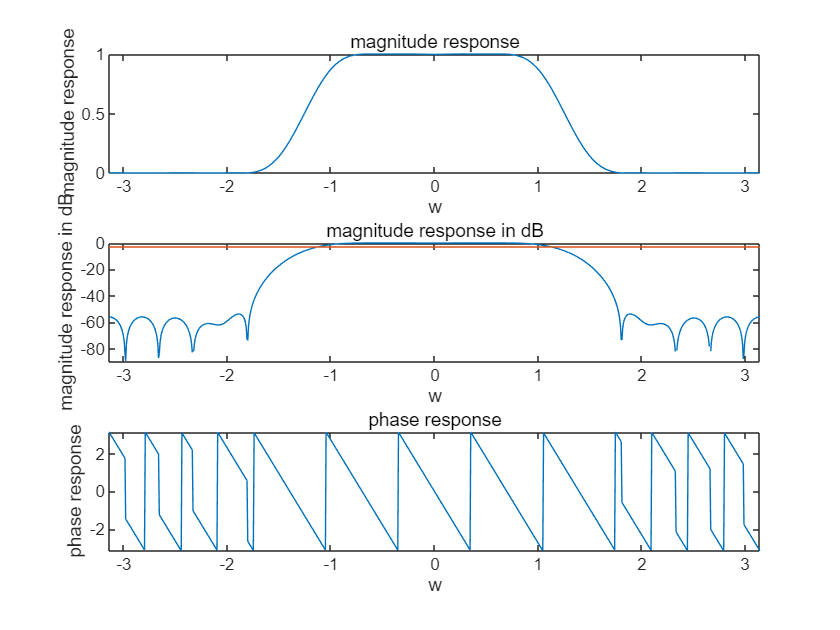

h=[-0.0035,-0.0039,0.0072,0.0201,-0.0000,-0.0517,-0.0506,0.0855,0.2965,0.4008,0.2965,0.0855,-0.0506,-0.0517,-0.0000,0.0201,0.0072,-0.0039,-0.0035];

figure();
[mag,phase]=FreRes(h,1);
syms w;
figure()

subplot(3,1,1);
fplot(w,mag,[-pi,pi]);
xlabel('w');
ylabel('magnitude response');
title('magnitude response');

subplot(3,1,2);
fplot(w,20*log10(mag),[-pi,pi]);
xlabel('w');
ylabel('magnitude response in dB');
title('magnitude response in dB');
hold on;
plot(linspace(-pi,pi,1000),-3*ones(1,1000));

subplot(3,1,3);
fplot(w,phase,[-pi,pi]);
xlabel('w');
ylabel('phase response');
title('phase response');

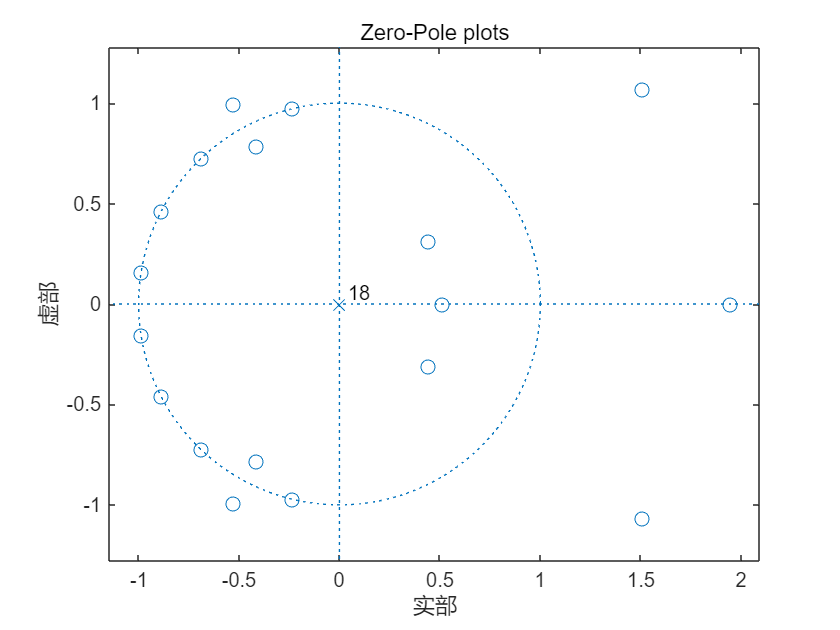



figure();
P=h;
D=[1, zeros(1,18)];
Zeros = roots(P);
poles = roots(D);
zplane(Zeros,poles);
title('Zero-Pole plots');

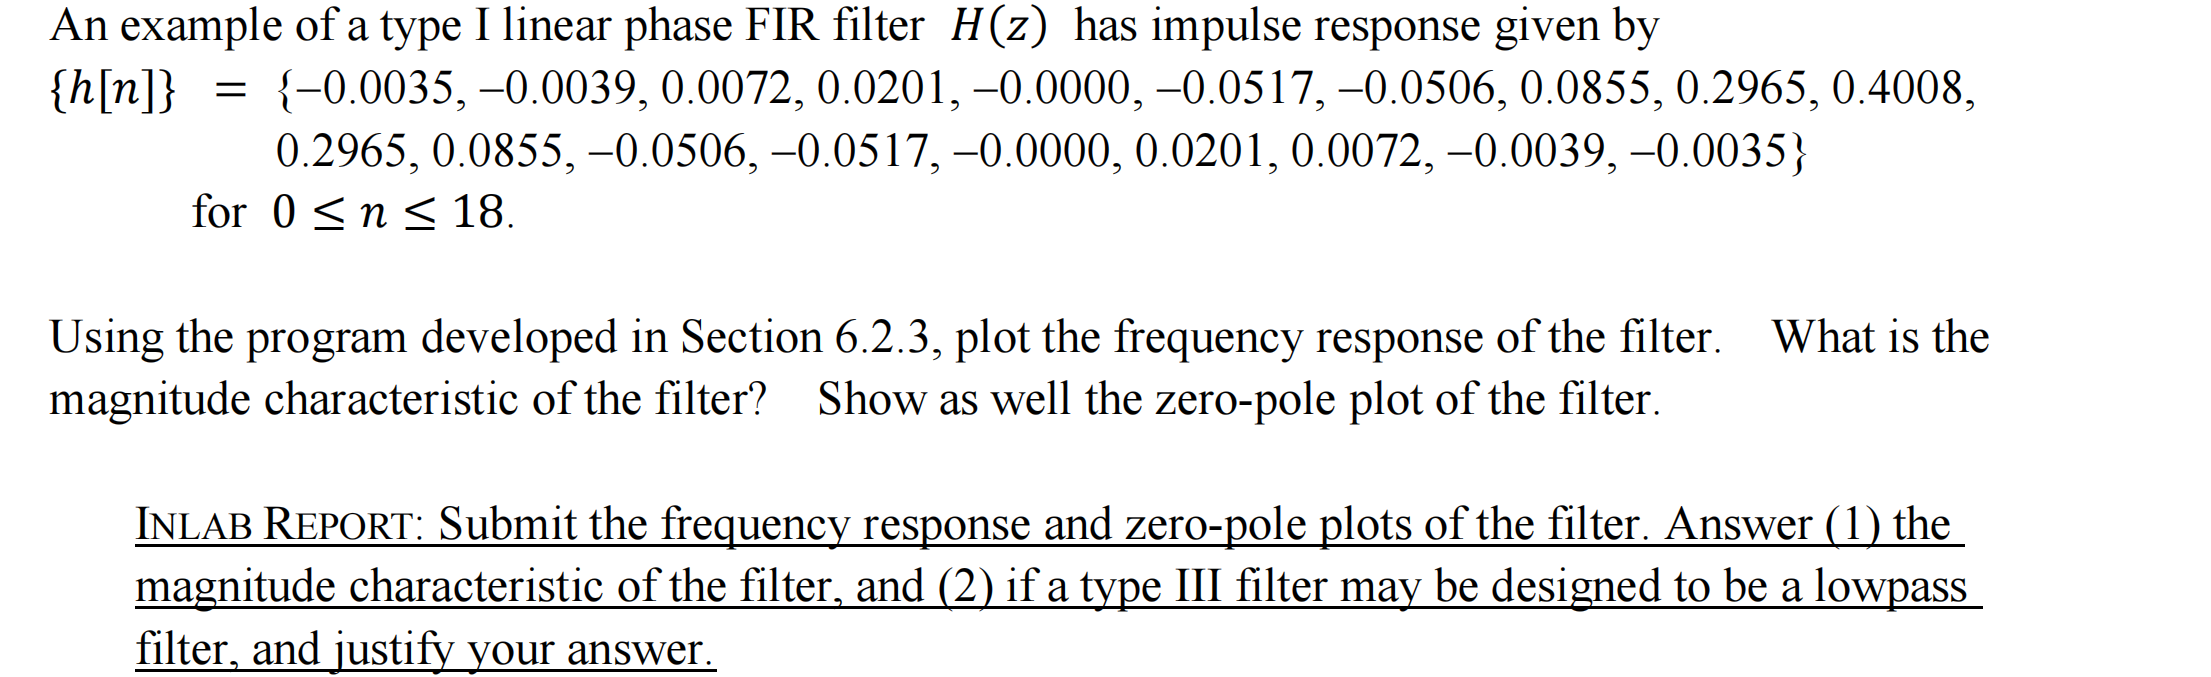

(1):低通滤波器，

Additionally, it does not exhibit a zero phase across all frequencies

Cutoff frequency is about -1.13 and +1.13

????This type of filter has either an even number or no zeros at 𝑧 = 1 and 𝑧 =−1.

(2)type3不可能作为低通，构造反对称序列

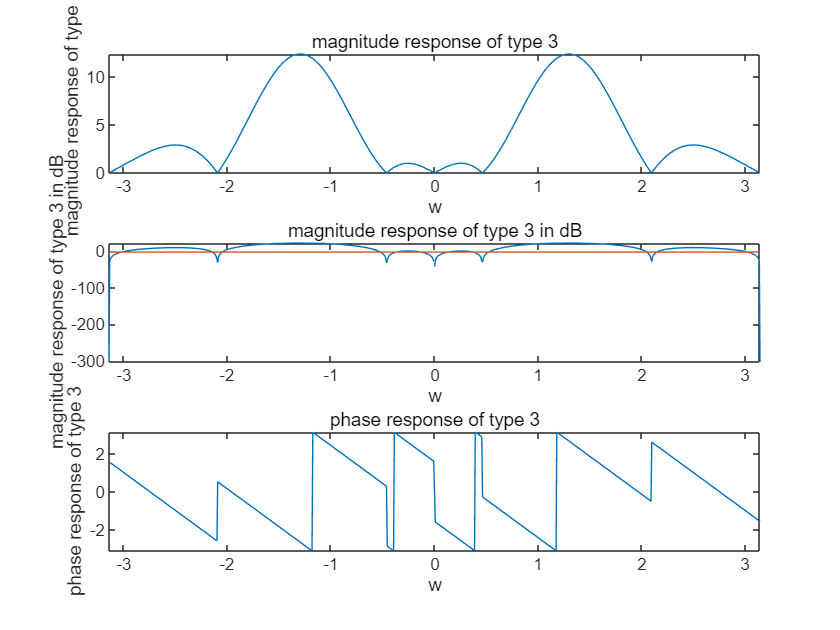


h_type3 = [-1 -2 2 3 0 -3 -2 2 1];
[mag2,phase2]=FreRes(h_type3,1);
syms w;
figure();

subplot(3,1,1);
fplot(w,mag2,[-pi,pi]);
xlabel('w');
ylabel('magnitude response of type 3');
title('magnitude response of type 3');

subplot(3,1,2);
fplot(w,20*log10(mag2),[-pi,pi]);
xlabel('w');
ylabel('magnitude response of type 3 in dB');
title('magnitude response of type 3 in dB');
hold on;
plot(linspace(-pi,pi,1000),-3*ones(1,1000));

subplot(3,1,3);
fplot(w,phase2,[-pi,pi]);
xlabel('w');
ylabel('phase response of type 3');
title('phase response of type 3');

% (2):No, it can be a bandpass filter,频谱在0是小，反例

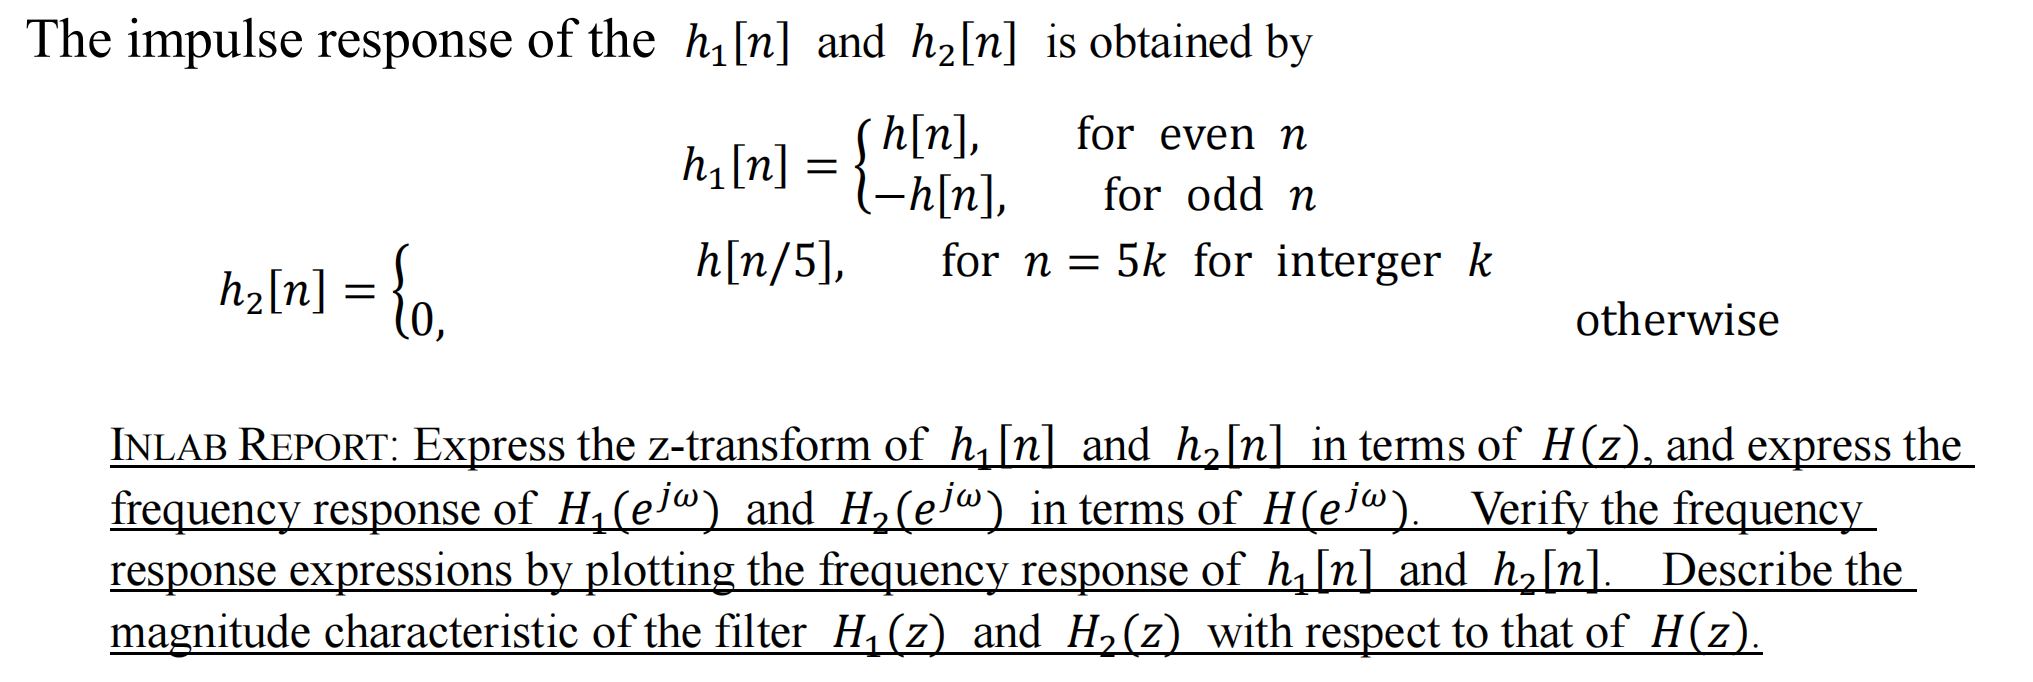

n=0:18;
h=[-0.0035,-0.0039,0.0072,0.0201,-0.0000,-0.0517,-0.0506,0.0855,0.2965,0.4008,0.2965,0.0855,-0.0506,-0.0517,-0.0000,0.0201,0.0072,-0.0039,-0.0035];
h1=h;
h2=zeros(1,91);
h1(2:2:19)=-h1(2:2:19);
h2(1:5:91)=h(1:1:19);
syms w;

[mag1,phase1]=FreRes(h1,1);
[mag2,phase2]=FreRes(h2,1);

figure();
sgtitle('H_1(z) ');
subplot(3,1,1);
fplot(w,mag1,[-pi,pi]);
xlabel('w');
ylabel('magnitude response');
title('magnitude response');

subplot(3,1,2);
fplot(w,20*log10(mag1),[-pi,pi]);
xlabel('w');
ylabel('magnitude response in dB');
title('magnitude response in dB');

subplot(3,1,3);
fplot(w,phase1,[-pi,pi]);
xlabel('w');
ylabel('phase response');
title('phase response');

figure();
sgtitle('H_2(z)');
subplot(3,1,1);
fplot(w,mag2,[-pi,pi]);
xlabel('w');
ylabel('magnitude response');
title('magnitude response');

subplot(3,1,2);
fplot(w,20*log10(mag2),[-pi,pi]);
xlabel('w');
ylabel('magnitude response in dB');
title('magnitude response in dB');

subplot(3,1,3);
fplot(w,phase2,[-pi,pi]);
xlabel('w');
ylabel('phase response');
title('phase response');

**6.3.2 Design of Simple FIR Filters**

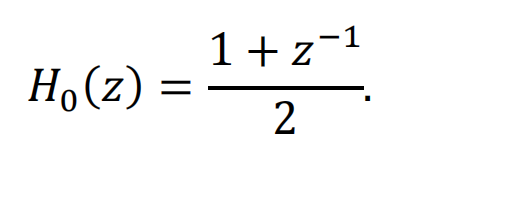

Design a linear phase lowpass FIR filter with a 3-dB cutoff frequency at 0.3𝜋 

w = linspace(0,pi,4000);
% M = -1/2*log2(cos(wc/2)) 
M = 3;
H_cascade = exp(-j*3*w/2).*(cos(w/2)).^3;
H_moving_average = (1/M)*sin(M.*w/2)./sin(w/2).*exp(-1j*(M-1).*w./2);
figure
plot(w,20*log10(abs(H_cascade)));
hold on;
plot(w,20*log10(abs(H_moving_average)));
plot(w,-3*ones(1,4000));
ylim([-50,0]);
xlabel('w');
ylabel('magnitude response in dB');

legend('cascade filter','higher order moving average filter','-3dB ');
hold off

**6.4 IIR Filters**

Design a first order highpass IIR filter with a 3-dB cutoff frequency of 0.2 𝜋. 

a = (1-sin(0.2*pi))/cos(0.2*pi);
w = linspace(0,pi,4000);
H = sqrt(((1+a)^2*(1-cos(w)))./(2*(1+a^2-2*a*cos(w))));
figure
plot(w,20*log10(abs(H)));
hold on;
plot(w,-3*ones(1,4000));
xlabel('w');
ylabel('magnitude response in dB');
title('highpass IIR filter ');
legend('highpass IIR filter','3-dB cutoff line');